# OptKnock Tutorial

## Author: Sebastián N. Mendoza,  Center for Mathematical Modeling, University of Chile. snmendoz@uc.cl

## **Reviewer(s): Thomas Pfau, Sylvian Arreckx, Laurent Heirendt, Ronan Fleming, John Sauls, Anne Richelle**

## **INTRODUCTION:**

OptKnock is an algorithm suggesting the genetic manipulation that lead to the overproduction of a specified metabolite [1]. Opknock pinpoints which set of reactions to to remove (i.e. delettion of the genes associated to these reactions) from a metabolic network to obtain a mutant that will produce a particular target of interest at a higher rate than the wild-type strain. 

For example, imagine that we would like to increase the production of succinate or lactate in* Escherichia coli*. Which are the knock-outs needed to increase the production of these products? We will approach these problems in this tutorial.

## MATERIALS & EQUIPMENT

- MATLAB

- A solver for Mixed Integer Linear Programming (MILP) problems.Use changeCobraSolver to choose the solver for MILP problems (e.g., Gurobi).

## PROCEDURE

The proceduce consists on the following steps: 

1) Constrain the model.

2) Define the set of reactions that will be used to search knockouts. Note : only reactions in this set will be deleted. 

3) Define the number of reactions to be deleted, the target reaction and some constraints to be accomplish.

4) Run optKnock. 

**TIMING: **This task should take from a few seconds to a few hours depending on the size of your reconstruction.

Verify that cobratoolbox has been initialized and that the solver has been set.

global TUTORIAL_INIT_CB;
if ~isempty(TUTORIAL_INIT_CB) && TUTORIAL_INIT_CB==1
    initCobraToolbox
end

changeCobraSolver('gurobi','all');
fullPath = which('tutorial_optKnock');
folder = fileparts(fullPath);
currectDirectory = pwd;
cd(folder);


Load the model of E. coli [2].

modelFileName = 'iJO1366.mat';
modelDirectory = getDistributedModelFolder(modelFileName); %Look up the folder for the distributed Models.
modelFileName= [modelDirectory filesep modelFileName]; % Get the full path. Necessary to be sure, that the right model is loaded
model = readCbModel(modelFileName);

biomass = 'BIOMASS_Ec_iJO1366_core_53p95M';

Define the maximum number of solutions to find (i.e., maximum number of remvable reactions that lead to the overproduction of the metabolite of interest)

threshold = 5;

Define the set of reactions that will be used to search knockouts. Note : only reactions in this set will be deleted

selectedRxnList = {'GLCabcpp'; 'GLCptspp'; 'HEX1'; 'PGI'; 'PFK'; 'FBA'; 'TPI'; 'GAPD'; ...
                   'PGK'; 'PGM'; 'ENO'; 'PYK'; 'LDH_D'; 'PFL'; 'ALCD2x'; 'PTAr'; 'ACKr'; ...
                   'G6PDH2r'; 'PGL'; 'GND'; 'RPI'; 'RPE'; 'TKT1'; 'TALA'; 'TKT2'; 'FUM'; ...
                   'FRD2'; 'SUCOAS'; 'AKGDH'; 'ACONTa'; 'ACONTb'; 'ICDHyr'; 'CS'; 'MDH'; ...
                   'MDH2'; 'MDH3'; 'ACALD'};



 > Gurobi interface added to MATLAB path.
 > Solver for LP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MILP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for QP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > Solver for MIQP problems has been set to gurobi.
 > Solver gurobi not supported for problems of type NLP. No solver set for this problemtype 


Constraint the model with biological assumptions

% prespecified amount of glucose uptake 10 mmol/grDW*hr
model = changeRxnBounds(model, 'EX_glc__D_e', -10, 'b');

% Unconstrained uptake routes for inorganic phosphate, sulfate and
% ammonia
Exchange={'EX_o2_e';'EX_pi_e';'EX_so4_e'; 'EX_nh4_e'};
Bounds=[0;-1000;-1000;-1000];
model = changeRxnBounds(model, Exchange, Bounds, 'l');

% Enable secretion routes  for acetate, carbon dioxide, ethanol, formate, lactate
% and succinate
Exchange={'EX_ac_e';'EX_co2_e';'EX_etoh_e';'EX_for_e';'EX_lac__D_e';'EX_succ_e'};
Bounds=[1000;1000;1000;1000;1000;1000];
model = changeRxnBounds(model, Exchange, Bounds, 'u');

% Constrain the phosphotransferase system
model = changeRxnBounds(model, 'GLCabcpp', -1000, 'l');
model = changeRxnBounds(model, 'GLCptspp', -1000, 'l');
model = changeRxnBounds(model, 'GLCabcpp', 1000, 'u');
model = changeRxnBounds(model, 'GLCptspp', 1000, 'u');
model = changeRxnBounds(model, 'GLCt2pp', 0, 'b');


Then, calculates the production of metabolites before running optKnock.

% determine succinate production and growth rate
fbaWT = optimizeCbModel(model);
succFluxWT = fbaWT.x(strcmp(model.rxns, 'EX_succ_e'));
etohFluxWT = fbaWT.x(strcmp(model.rxns, 'EX_etoh_e'));
formFluxWT = fbaWT.x(strcmp(model.rxns, 'EX_for_e'));
lactFluxWT = fbaWT.x(strcmp(model.rxns, 'EX_lac__D_e'));
acetFluxWT = fbaWT.x(strcmp(model.rxns, 'EX_ac_e'));
growthRateWT = fbaWT.f;
fprintf('The production of succinate before optimization is %.1f \n', succFluxWT);
fprintf('The growth rate before optimization is %.1f \n', growthRateWT);
fprintf(['The production of other products such as ethanol, formate, lactate and'...
         'acetate are %.1f, %.1f, %.1f and %.1f, respectively. \n'], ...
        etohFluxWT, formFluxWT, lactFluxWT, acetFluxWT);

**I) EXAM****PLE**** 1 : SUCCINATE**** OVERPRODUCTION**

**Aim:** **finding optKnock reaction****s sets of size 2 for increasing production of succinate**

fprintf('\n...EXAMPLE 1: Finding optKnock sets of size 2 or less...\n\n')
% Set optKnock options
% The exchange of succinate will be the objective of the outer problem
options = struct('targetRxn', 'EX_succ_e', 'numDel', 2);
% We will impose that biomass be at least 50% of the biomass of wild-type
constrOpt = struct('rxnList', {{biomass}},'values', 0.5*fbaWT.f, 'sense', 'G');
% We will try to find 10 optKnock sets of a maximun length of 2
previousSolutions = cell(10, 1);
contPreviousSolutions = 1;
nIter = 1;
while nIter < threshold
    fprintf('...Performing optKnock analysis...\n')
    if isempty(previousSolutions{1})
        optKnockSol = OptKnock(model, selectedRxnList, options, constrOpt);
    else
        optKnockSol = OptKnock(model, selectedRxnList, options, constrOpt, previousSolutions, 1);
    end
    
    % determine succinate production and growth rate after optimization
    succFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_succ_e'));
    growthRateM1 = optKnockSol.fluxes(strcmp(model.rxns, biomass));
    etohFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_etoh_e'));
    formFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_for_e'));
    lactFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_lac__D_e'));
    acetFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_ac_e'));
    setM1 = optKnockSol.rxnList;
    
    if ~isempty(setM1)


...EXAMPLE 1: Finding optKnock sets of size 2 or less...



        previousSolutions{contPreviousSolutions} = setM1;
        contPreviousSolutions = contPreviousSolutions + 1;
        %printing results
        fprintf('optKnock found a optKnock set of large %d composed by ', length(setM1));
        for j = 1:length(setM1)
            if j == 1
                fprintf('%s', setM1{j});
            elseif j == length(setM1)
                fprintf(' and %s', setM1{j});
            else
                fprintf(', %s', setM1{j});
            end
        end
        fprintf('\n');
        fprintf('The production of succinate after optimization is %.2f \n', succFluxM1);
        fprintf('The growth rate after optimization is %.2f \n', growthRateM1);
        fprintf(['The production of other products such as ethanol, formate, lactate and acetate are' ...
                 '%.1f, %.1f, %.1f and %.1f, respectively. \n'], etohFluxM1, formFluxM1, lactFluxM1, acetFluxM1);
        fprintf('...Performing coupling analysis...\n');
        [type, maxGrowth, maxProd, minProd] = analyzeOptKnock(model, setM1, 'EX_succ_e');
        fprintf('The solution is of type: %s\n', type);
        fprintf('The maximun growth rate given the optKnock set is %.2f\n', maxGrowth);
        fprintf(['The maximun and minimun production of succinate given the optKnock set is ' ...
                 '%.2f and %.2f, respectively \n\n'], minProd, maxProd);
        if strcmp(type, 'growth coupled')
            singleProductionEnvelope(model, setM1, 'EX_succ_e', biomass, 'savePlot', 1, 'showPlot', 1, ...
                                     'fileName', ['succ_ex1_' num2str(nIter)], 'outputFolder', 'OptKnockResults');
        end,
    else
        if nIter == 1
            fprintf('optKnock was not able to found an optKnock set\n');
        else
            fprintf('optKnock was not able to found additional optKnock sets\n');
        end
        break;
    end
    nIter = nIter + 1;
end

**II) EXAM****PLE**** 2: SUCCINATE**** OVERPRODUCTION**

**Aim : finding optKnock reactions sets of size 3 for increasing production of succinate**

fprintf('\n...EXAMPLE 1: Finding optKnock sets of size 3...\n\n')
% Set optKnock options
% The exchange of succinate will be the objective of the outer problem
options = struct('targetRxn', 'EX_succ_e', 'numDel', 3);
% We will impose that biomass be at least 50% of the biomass of wild-type
constrOpt = struct('rxnList', {{biomass}}, 'values', 0.5*fbaWT.f, 'sense', 'G');
% We will try to find 10 optKnock sets of a maximun length of 3
nIter = 1;
while nIter < threshold
    fprintf('...Performing optKnock analysis...')
    if isempty(previousSolutions{1})
        optKnockSol = OptKnock(model, selectedRxnList, options, constrOpt);
    else
        optKnockSol = OptKnock(model, selectedRxnList, options, constrOpt, previousSolutions);
    end
    
    % determine succinate production and growth rate after optimization
    succFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_succ_e'));
    growthRateM1 = optKnockSol.fluxes(strcmp(model.rxns, biomass));
    etohFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_etoh_e'));
    formFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_for_e'));
    lactFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_lac__D_e'));
    acetFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_ac_e'));
    setM1 = optKnockSol.rxnList;
    
    if ~isempty(setM1)
        previousSolutions{contPreviousSolutions} = setM1;

...Performing optKnock analysis...


optKnock found a optKnock set of large 2 composed by 

PFL

 and RPI

The production of succinate after optimization is 2.75 


The growth rate after optimization is 0.14 


The production of other products such as ethanol, formate, lactate and acetate are9.4, 0.0, -0.0 and 0.0, respectively. 


...Performing coupling analysis...


The solution is of type: growth coupled non unique


The maximun growth rate given the optKnock set is 0.12


The maximun and minimun production of succinate given the optKnock set is 0.04 and 2.31, respectively 



...Performing optKnock analysis...


MILP problem with 8398 constraints 63 integer variables and 8370 continuous variables
Optimize a model with 8398 rows, 8370 columns and 34671 nonzeros
Variable types: 8307 continuous, 63 integer (63 binary)
Coefficient statistics:
  Matrix range     [2e-06, 1e+03]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e+00, 1e+03]
  RHS range        [1e-02, 1e+03]
Presolve removed 5079 rows and 3321 columns
Presolve time: 0.09s
Presolved: 3319 rows, 5049 columns, 21617 nonzeros
Variable types: 5012 continuous, 37 integer (37 binary)

Root relaxation: objective 1.230321e+01, 4944 iterations, 0.64 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   12.30321    0    2          -   12.30321      -     -    1s
H    0     0                       0.0915893   12.30321      -     -    1s
     0     0   12.30321    0    2    0.09159   12.30321      -     -    1s
     0     2

optKnock found a optKnock set of large 2 composed by 

PFL

 and TKT2

The production of succinate after optimization is 1.68 


The growth rate after optimization is 0.22 


The production of other products such as ethanol, formate, lactate and acetate are14.9, 0.0, 0.0 and -0.0, respectively. 


...Performing coupling analysis...


The solution is of type: growth coupled non unique


The maximun growth rate given the optKnock set is 0.18


The maximun and minimun production of succinate given the optKnock set is 0.06 and 1.41, respectively 



...Performing optKnock analysis...


MILP problem with 8399 constraints 63 integer variables and 8370 continuous variables
Optimize a model with 8399 rows, 8370 columns and 34674 nonzeros
Variable types: 8307 continuous, 63 integer (63 binary)
Coefficient statistics:
  Matrix range     [2e-06, 1e+03]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e+00, 1e+03]
  RHS range        [1e-02, 1e+03]
Presolve removed 5079 rows and 3321 columns
Presolve time: 0.10s
Presolved: 3320 rows, 5049 columns, 21619 nonzeros
Variable types: 5012 continuous, 37 integer (37 binary)

Root relaxation: objective 1.230321e+01, 5180 iterations, 0.69 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   12.30321    0    2          -   12.30321      -     -    1s
H    0     0                       0.0915893   12.30321      -     -    1s
     0     0   12.30321    0    2    0.09159   12.30321      -     -    1s
     0     2

optKnock found a optKnock set of large 2 composed by 

PFL

 and RPE

The production of succinate after optimization is 1.44 


The growth rate after optimization is 0.22 


The production of other products such as ethanol, formate, lactate and acetate are0.0, 0.0, 15.2 and 0.0, respectively. 


...Performing coupling analysis...


The solution is of type: growth coupled non unique


The maximun growth rate given the optKnock set is 0.18


The maximun and minimun production of succinate given the optKnock set is 0.06 and 1.22, respectively 



...Performing optKnock analysis...


MILP problem with 8400 constraints 63 integer variables and 8370 continuous variables
Optimize a model with 8400 rows, 8370 columns and 34677 nonzeros
Variable types: 8307 continuous, 63 integer (63 binary)
Coefficient statistics:
  Matrix range     [2e-06, 1e+03]
  Objective range  [1e+00, 1e+00]
  Bounds range     [1e+00, 1e+03]
  RHS range        [1e-02, 1e+03]
Presolve removed 5079 rows and 3321 columns
Presolve time: 0.09s
Presolved: 3321 rows, 5049 columns, 21621 nonzeros
Variable types: 5012 continuous, 37 integer (37 binary)

Root relaxation: objective 1.230321e+01, 4774 iterations, 0.63 seconds

    Nodes    |    Current Node    |     Objective Bounds      |     Work
 Expl Unexpl |  Obj  Depth IntInf | Incumbent    BestBd   Gap | It/Node Time

     0     0   12.30321    0    2          -   12.30321      -     -    1s
H    0     0                       0.0915893   12.30321      -     -    1s
     0     0   12.30321    0    2    0.09159   12.30321      -     -    1s
     0     2

optKnock found a optKnock set of large 2 composed by 

PFL

 and TALA

The production of succinate after optimization is 1.20 


The growth rate after optimization is 0.22 


The production of other products such as ethanol, formate, lactate and acetate are15.4, 0.0, -0.0 and 0.0, respectively. 


...Performing coupling analysis...


The solution is of type: growth coupled non unique


The maximun growth rate given the optKnock set is 0.19


The maximun and minimun production of succinate given the optKnock set is 0.06 and 1.01, respectively 



        contPreviousSolutions=contPreviousSolutions + 1;
        %printing results
        fprintf('optKnock found a optKnock set of large %d composed by ',length(setM1));
        for j = 1:length(setM1)


...EXAMPLE 1: Finding optKnock sets of size 3...



            if j == 1
                fprintf('%s',setM1{j});
            elseif j == length(setM1)
                fprintf(' and %s',setM1{j});
            else
                fprintf(', %s',setM1{j});
            end
        end
        fprintf('\n');
        fprintf('The production of succinate after optimization is %.2f \n', succFluxM1);
        fprintf('The growth rate after optimization is %.2f \n', growthRateM1);
        fprintf(['The production of other products such as ethanol, formate, lactate and acetate are ' ...
                 '%.1f, %.1f, %.1f and %.1f, respectively. \n'], etohFluxM1, formFluxM1, lactFluxM1, acetFluxM1);
        fprintf('...Performing coupling analysis...\n');
        [type, maxGrowth, maxProd, minProd] = analyzeOptKnock(model, setM1, 'EX_succ_e');
        fprintf('The solution is of type: %s\n', type);
        fprintf('The maximun growth rate given the optKnock set is %.2f\n', maxGrowth);
        fprintf(['The maximun and minimun production of succinate given the optKnock set is ' ...
                 '%.2f and %.2f, respectively \n\n'], minProd, maxProd);
        if strcmp(type,'growth coupled')
            singleProductionEnvelope(model, setM1, 'EX_succ_e', biomass, 'savePlot', 1, 'showPlot', 1, ...
                                     'fileName', ['succ_ex2_' num2str(nIter)], 'outputFolder', 'OptKnockResults');
        end
    else
        if nIter == 1
            fprintf('optKnock was not able to found an optKnock set\n');
        else
            fprintf('optKnock was not able to found additional optKnock sets\n');
        end
        break;
    end
    nIter = nIter + 1;
end

**III) EXAMPLE 3 : LACTATE OVERPRODUCTION**

**Aim: finding optKnock reactions sets of size 3 for increasing production of lactate**

...Performing optKnock analysis...

optKnock found a optKnock set of large 3 composed by 

ALCD2x

, LDH_D

 and PFL

The production of succinate after optimization is 8.81 


The growth rate after optimization is 0.15 


The production of other products such as ethanol, formate, lactate and acetate are 0.0, 0.0, -0.0 and 1.7, respectively. 


...Performing coupling analysis...


The solution is of type: growth coupled


The maximun growth rate given the optKnock set is 0.11


The maximun and minimun production of succinate given the optKnock set is 9.11 and 9.11, respectively 



...Performing optKnock analysis...

optKnock found a optKnock set of large 3 composed by 

ACALD

, LDH_D

 and PFL

The production of succinate after optimization is 8.81 


The growth rate after optimization is 0.15 


The production of other products such as ethanol, formate, lactate and acetate are 0.0, 0.0, -0.0 and 4.1, respectively. 


...Performing coupling analysis...


The solution is of type: growth coupled non unique


The maximun growth rate given the optKnock set is 0.11


The maximun and minimun production of succinate given the optKnock set is 4.23 and 9.11, respectively 



...Performing optKnock analysis...

optKnock found a optKnock set of large 2 composed by 

PFL

 and TKT1

The production of succinate after optimization is 1.20 


The growth rate after optimization is 0.22 


The production of other products such as ethanol, formate, lactate and acetate are 0.0, 0.0, 15.4 and 0.0, respectively. 


...Performing coupling analysis...


The solution is of type: growth coupled non unique


The maximun growth rate given the optKnock set is 0.19


The maximun and minimun production of succinate given the optKnock set is 0.06 and 1.01, respectively 



...Performing optKnock analysis...

optKnock found a optKnock set of large 3 composed by 

ACALD

, ALCD2x

 and PFL

The production of succinate after optimization is 0.95 


The growth rate after optimization is 0.22 


The production of other products such as ethanol, formate, lactate and acetate are 0.0, 0.0, 15.7 and -0.0, respectively. 


...Performing coupling analysis...


The solution is of type: growth coupled non unique


The maximun growth rate given the optKnock set is 0.19


The maximun and minimun production of succinate given the optKnock set is 0.06 and 0.80, respectively 



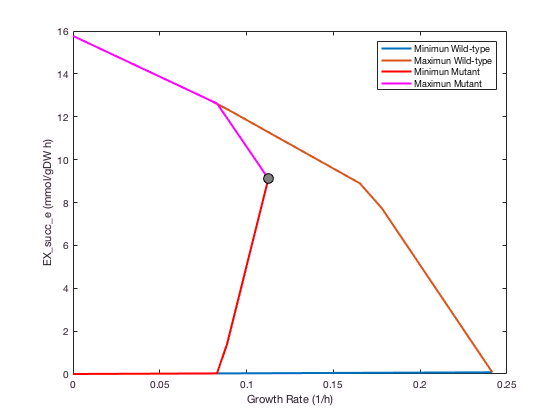

fprintf('\n...EXAMPLE 1: Finding optKnock sets of size 3...\n\n')
% Set optKnock options
% The exchange of lactate will be the objective of the outer problem
options = struct('targetRxn', 'EX_lac__D_e', 'numDel', 3);
% We will impose that biomass be at least 50% of the biomass of wild-type
constrOpt = struct('rxnList', {{biomass}}, 'values', 0.5*fbaWT.f, 'sense', 'G');
% We will try to find 10 optKnock sets of a maximun length of 6
previousSolutions = cell(100, 1);
contPreviousSolutions = 1;
nIter = 1;
while nIter < threshold
    fprintf('...Performing optKnock analysis...')
    if isempty(previousSolutions{1})
        optKnockSol = OptKnock(model, selectedRxnList, options, constrOpt);
    else
        optKnockSol = OptKnock(model, selectedRxnList, options, constrOpt, previousSolutions);
    end
    
    % determine lactate production and growth rate after optimization
    lactFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_lac__D_e'));
    growthRateM1 = optKnockSol.fluxes(strcmp(model.rxns, biomass));
    etohFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_etoh_e'));
    formFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_for_e'));
    succFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_succ_e'));
    acetFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_ac_e'));
    setM1 = optKnockSol.rxnList;
    
    if ~isempty(setM1)
        previousSolutions{contPreviousSolutions} = setM1;
        contPreviousSolutions=contPreviousSolutions + 1;

        %printing results
        fprintf('optKnock found a optKnock set of large %d composed by ',length(setM1));
        for j = 1:length(setM1)
            if j == 1


...EXAMPLE 1: Finding optKnock sets of size 3...



                fprintf('%s', setM1{j});
            elseif j == length(setM1)
                fprintf(' and %s', setM1{j});
            else
                fprintf(', %s', setM1{j});
            end
        end
        fprintf('\n');
        fprintf('The production of lactate after optimization is %.2f \n', lactFluxM1);
        fprintf('The growth rate after optimization is %.2f \n', growthRateM1);
        fprintf(['The production of other products such as ethanol, formate, succinate and acetate are ' ...
                 '%.1f, %.1f, %.1f and %.1f, respectively. \n'], etohFluxM1, formFluxM1, succFluxM1, acetFluxM1);
        fprintf('...Performing coupling analysis...\n');
        [type, maxGrowth, maxProd, minProd] = analyzeOptKnock(model, setM1, 'EX_lac__D_e');
        fprintf('The solution is of type: %s\n', type);
        fprintf('The maximun growth rate given the optKnock set is %.2f\n', maxGrowth);
        fprintf(['The maximun and minimun production of lactate given the optKnock set is ' ...
                 '%.2f and %.2f, respectively \n\n'], minProd, maxProd);
        singleProductionEnvelope(model, setM1, 'EX_lac__D_e', biomass, 'savePlot', 1, 'showPlot', 1, ...
                                 'fileName', ['lact_ex1_' num2str(nIter)], 'outputFolder', 'OptKnockResults');
    else
        if nIter == 1
            fprintf('optKnock was not able to found an optKnock set\n');
        else
            fprintf('optKnock was not able to found additional optKnock sets\n');
        end
        break;
    end
    nIter = nIter + 1;
end

**IV) EXAMPLE 4 : LACTATE OVERPRODUCTION**

**Aim: finding optKnock reactions sets of size 6 for increasing production of lactate**

...Performing optKnock analysis...

optKnock found a optKnock set of large 3 composed by 

GLCabcpp

, PFL

 and PGI

The production of lactate after optimization is 18.13 


The growth rate after optimization is 0.12 


The production of other products such as ethanol, formate, succinate and acetate are 0.0, 0.0, 0.0 and 0.0, respectively. 


...Performing coupling analysis...


The solution is of type: non unique


The maximun growth rate given the optKnock set is 0.08


The maximun and minimun production of lactate given the optKnock set is 0.00 and 18.72, respectively 



...Performing optKnock analysis...

optKnock found a optKnock set of large 2 composed by 

PFL

 and PGI

The production of lactate after optimization is 18.13 


The growth rate after optimization is 0.12 


The production of other products such as ethanol, formate, succinate and acetate are 0.0, 0.0, 0.0 and 0.0, respectively. 


...Performing coupling analysis...


The solution is of type: non unique


The maximun growth rate given the optKnock set is 0.08


The maximun and minimun production of lactate given the optKnock set is 0.00 and 18.72, respectively 



...Performing optKnock analysis...

optKnock found a optKnock set of large 3 composed by 

GND

, PGI

 and PTAr

The production of lactate after optimization is 18.01 


The growth rate after optimization is 0.12 


The production of other products such as ethanol, formate, succinate and acetate are 0.0, 0.6, 0.0 and 0.1, respectively. 


...Performing coupling analysis...


The solution is of type: non unique


The maximun growth rate given the optKnock set is 0.09


The maximun and minimun production of lactate given the optKnock set is 0.00 and 18.64, respectively 



...Performing optKnock analysis...

optKnock found a optKnock set of large 3 composed by 

ACKr

, GND

 and PGI

The production of lactate after optimization is 18.01 


The growth rate after optimization is 0.12 


The production of other products such as ethanol, formate, succinate and acetate are 0.0, 0.6, 0.0 and 0.1, respectively. 


...Performing coupling analysis...


The solution is of type: non unique


The maximun growth rate given the optKnock set is 0.09


The maximun and minimun production of lactate given the optKnock set is 0.00 and 18.64, respectively 



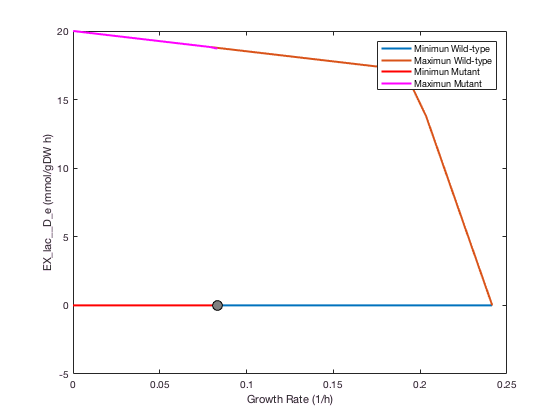

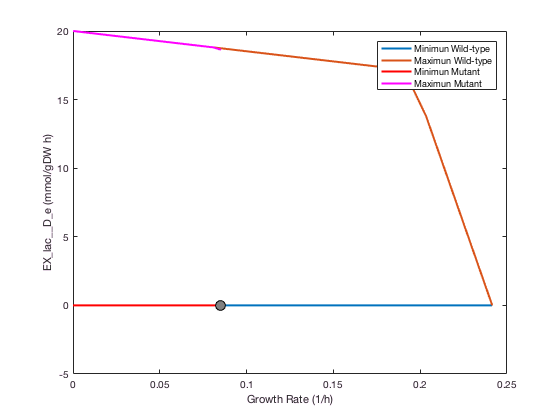

fprintf('...EXAMPLE 3: Finding optKnock sets of size 6...\n')
% Set optKnock options
% The exchange of lactate will be the objective of the outer problem
options = struct('targetRxn', 'EX_lac__D_e', 'numDel', 6);
% We will impose that biomass be at least 50% of the biomass of wild-type
constrOpt = struct('rxnList', {{biomass}}, 'values', 0.5*fbaWT.f, 'sense', 'G');
% We will try to find 10 optKnock sets of a maximun length of 2
nIter = 1;
while nIter < threshold
    fprintf('...Performing optKnock analysis...')
    if isempty(previousSolutions{1})
        optKnockSol = OptKnock(model, selectedRxnList, options, constrOpt);
    else
        optKnockSol = OptKnock(model, selectedRxnList, options, constrOpt, previousSolutions);
    end
    
    % determine lactate production and growth rate after optimization
    lactFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_lac__D_e'));
    growthRateM1 = optKnockSol.fluxes(strcmp(model.rxns,biomass));
    etohFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_etoh_e'));
    formFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_for_e'));
    succFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_succ_e'));
    acetFluxM1 = optKnockSol.fluxes(strcmp(model.rxns, 'EX_ac_e'));
    setM1 = optKnockSol.rxnList;
    
    if ~isempty(setM1)
        previousSolutions{contPreviousSolutions} = setM1;
        contPreviousSolutions = contPreviousSolutions + 1;
        %printing results
        fprintf('optKnock found a optKnock set of large %d composed by ', length(setM1));
        for j = 1:length(setM1)
            if j == 1
                fprintf('%s', setM1{j});

            elseif j == length(setM1)
                fprintf(' and %s', setM1{j});
            else
                fprintf(', %s', setM1{j});

...EXAMPLE 3: Finding optKnock sets of size 6...


...Performing optKnock analysis...

optKnock found a optKnock set of large 4 composed by 

HEX1

, PGI

, PTAr

 and TKT1

The production of lactate after optimization is 17.99 


The growth rate after optimization is 0.12 


The production of other products such as ethanol, formate, succinate and acetate are 0.0, 0.7, 0.0 and 0.1, respectively. 


...Performing coupling analysis...


The solution is of type: non unique


The maximun growth rate given the optKnock set is 0.09


The maximun and minimun production of lactate given the optKnock set is 0.00 and 18.62, respectively 



...Performing optKnock analysis...

optKnock found a optKnock set of large 5 composed by 

GLCabcpp

, PGI

, PTAr

, PYK

 and TKT1

The production of lactate after optimization is 17.99 


The growth rate after optimization is 0.12 


The production of other products such as ethanol, formate, succinate and acetate are 0.0, 0.7, 0.0 and 0.1, respectively. 


...Performing coupling analysis...


The solution is of type: non unique


The maximun growth rate given the optKnock set is 0.09


The maximun and minimun production of lactate given the optKnock set is 0.00 and 18.62, respectively 



...Performing optKnock analysis...

optKnock found a optKnock set of large 4 composed by 

GLCabcpp

, PGI

, PTAr

 and TKT1

The production of lactate after optimization is 17.99 


The growth rate after optimization is 0.12 


The production of other products such as ethanol, formate, succinate and acetate are 0.0, 0.7, 0.0 and 0.1, respectively. 


...Performing coupling analysis...


The solution is of type: non unique


The maximun growth rate given the optKnock set is 0.09


The maximun and minimun production of lactate given the optKnock set is 0.00 and 18.62, respectively 



...Performing optKnock analysis...

optKnock found a optKnock set of large 6 composed by 

ACKr

, ALCD2x

, GLCabcpp

, PGI

, PYK

 and TKT1

The production of lactate after optimization is 17.99 


The growth rate after optimization is 0.12 


The production of other products such as ethanol, formate, succinate and acetate are 0.0, 0.7, 0.0 and 0.1, respectively. 


...Performing coupling analysis...


The solution is of type: growth coupled non unique


The maximun growth rate given the optKnock set is 0.09


The maximun and minimun production of lactate given the optKnock set is 10.38 and 18.62, respectively 



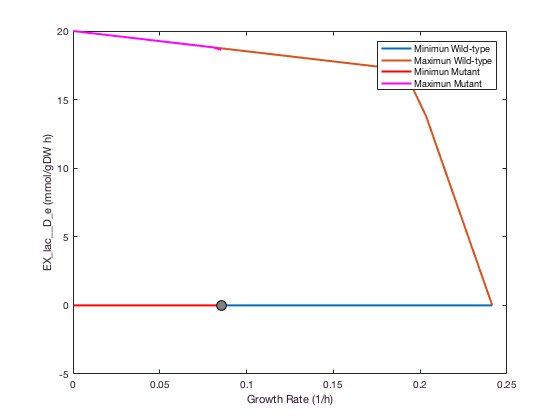

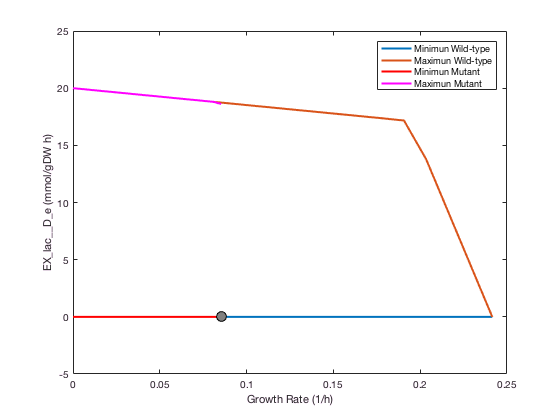

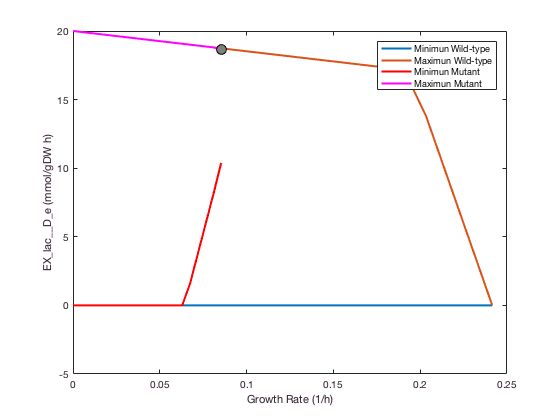

            end
        end
        fprintf('\n');
        fprintf('The production of lactate after optimization is %.2f \n', lactFluxM1);
        fprintf('The growth rate after optimization is %.2f \n', growthRateM1);
        fprintf(['The production of other products such as ethanol, formate, succinate and acetate are ' ...
                 '%.1f, %.1f, %.1f and %.1f, respectively. \n'], etohFluxM1, formFluxM1, succFluxM1, acetFluxM1);
        fprintf('...Performing coupling analysis...\n');
        [type, maxGrowth, maxProd, minProd] = analyzeOptKnock(model, setM1, 'EX_lac__D_e');
        fprintf('The solution is of type: %s\n', type);
        fprintf('The maximun growth rate given the optKnock set is %.2f\n', maxGrowth);
        fprintf(['The maximun and minimun production of lactate given the optKnock set is ' ...
                 '%.2f and %.2f, respectively \n\n'], minProd, maxProd);
        singleProductionEnvelope(model, setM1, 'EX_lac__D_e', biomass, 'savePlot', 1, 'showPlot', 1, ...
                                 'fileName', ['lact_ex2_' num2str(nIter)], 'outputFolder', 'OptKnockResults');
    else
        if nIter == 1
            fprintf('optKnock was not able to found an optKnock set\n');
        else
            fprintf('optKnock was not able to found additional optKnock sets\n');
        end
        break;
    end
    nIter = nIter + 1;
end
cd(currectDirectory);

## TIMING

- Example 1 ~ 1-2 minutes

- Example 2 ~ 1-2 minutes

- Example 3 ~ 1-2 minutes

- Example 4 ~ 1-2 minutes

## TROUBLESHOOTING

1) If the algorithm takes a long time to find a solution, it is possible that the search space is too large. You can reduce the search space using a smaller set of reactions in the input variable "*selectedRxnList*". 

2) The default number of deletions used by optKnock is 5. If the algorithm is returning more deletions than what you want, you can change the number of deletions using the input variable "*numDel*".

3) optKnock could find a solution that it is not useful for you. For example, you may think that a solution is very obvious or that it breaks some important biological contraints. If optKnock found a solution that you don't want to find, use the input variable "*prevSolutions*" to prevent that solution to be found. 

## ANTICIPATED RESULTS

The optKnock algorithm will find sets of reactions that, when removed from the model, will improve the production of the metabolite of interest (e.g., succinate and lactate). In this tutorial, once optKnock finds a solution, then the type of solution is determined (if the product is coupled with biomass formation or not). Some of the sets will generate a coupled solution, i.e., the production rate will increase as biomass formation increases. For these kind of reactions a plot will be generated using the function *singleProductionEnvelope* and will be saved in the folder *tutorials/optKnock/optKnockResults*.

When you find a solution with OptKnock, you should always verify the minumum and maximum production rate using the function *analizeOptKnock*. 

## References

[1] Burgard, A. P., Pharkya, P. & Maranas, C. D. (2003). OptKnock: A Bilevel Programming Framework for Identifying Gene Knockout Strategies for Microbial Strain Optimization. Biotechnology and Bioengineering, 84(6), 647–657. http://doi.org/10.1002/bit.10803.

[2] Orth, J. D., Conrad, T. M., Na, J., Lerman, J. A., Nam, H., Feist, A. M., & Palsson, B. Ø. (2011). A comprehensive genome‐scale reconstruction of Escherichia coli metabolism—2011. *Molecular systems biology*, *7*(1), 535.